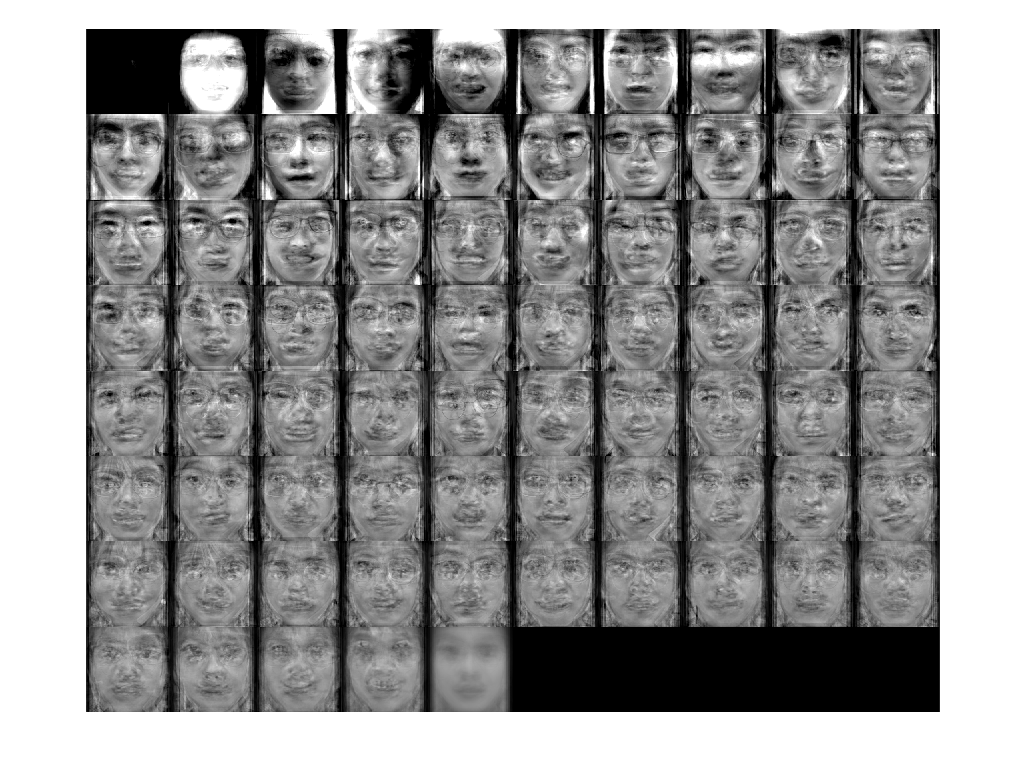

load eigendata.mat;


trans = gen_transformer(images,50);

% tic
% trans = gen_transformer(images,25);
% toc
% A = calc_data_mat(trans,test_images);
% tic
% classification(trans,A,test_labels);
% toc

%vis_face(trans.mean,trans);

%vis_eigen_face(trans,50);

eigen_face_grid = vis_eigen_faces(trans,10);
imshow(eigen_face_grid);

imwrite(eigen_face_grid,'eigen_faces.png');

% reconstruct

%vec = trans.A(:,30);
%cord = trans.bases'*vec;
%recon = trans.bases*cord;
%vis_face(vec+trans.mean,trans);
%vis_face(recon+trans.mean,trans);
%classification

%rate = classification(trans,trans.A,labels)
% test set
%AA = calc_data_mat(trans,test_images);
%rate = classification(trans,AA,test_labels)

% plot rates
%plot(train_rates); hold on;
%plot(test_rates); hold off;
%legend('training set','test set','Location','best');



function vis_face(vec,trans)
    img = reshape(vec,trans.img_height,trans.img_width);
    imshow(uint8(img));
end

function vis_eigen_face(trans,i)
    vec = trans.eigen_faces(:,i) + trans.mean;
    vis_face(vec,trans);
end

function rst = vis_eigen_faces(trans,N)
    M = ceil(trans.sample_size/N);
    rst = zeros(M*trans.img_height,N*trans.img_width,'uint8');
    for idx = 1:trans.sample_size
       r = floor((idx-1)/N);
       c = mod((idx-1),N);
       offset_r = trans.img_height*r;
       offset_c = trans.img_width*c;
       vec = trans.eigen_faces(:,idx)+trans.mean;
       img = reshape(vec,trans.img_height,trans.img_width);
       rst(offset_r+1:offset_r+trans.img_height,offset_c+1:offset_c+trans.img_width) = img;
    end
end

function frames = eig_frames(A,V,N)
    [sz1,sz2] = size(V);    
    frames = A' * V(:,1:N);
end

function transformer = gen_transformer(images,N)

    % calculate mean
    [i1,i2,i3] = size(images);
    flat_sz = i2*i3;
    sum = zeros(1,flat_sz);
    for i = 1:i1
        img = images(i,:);
        sum = sum+img;
    end
    avg = sum / i1;

    % get mean centered data matrix
    A = zeros(flat_sz,i1);
    for i=1:i1
        img = images(i,:);
        diff = img - avg;
        A(:,i) = diff;
    end
    
    % calclulate eigen faces
    ATA = A' * A;
    [V,D] = eig(ATA);
    
    evals = eig(ATA);
    [ev,ei] = sort(evals,'descend');
    eigen_vectors = V(:,ei);
    
    ef = A * eigen_vectors;
    
    % choose base
    bases = ef(:,1:N);
    bases = normc(bases);
    
    % choose regions
    
    projections = bases' * A;

    ref_means = zeros(N,15);

    for i = 1:15
        acc = zeros(N,1);
        for j=1:5
            acc = acc + projections(:,(i-1)*5+j);
        end
        ref_means(:,i) = acc/5;
    end
    
    % write data
    transformer.sample_size = i1;
    transformer.img_height = i2;
    transformer.img_width = i3;
    transformer.A = A;
    transformer.V = V;
    transformer.D = D;
    transformer.eigen_faces = ef;
    transformer.mean = avg';
    transformer.bases = bases;
    transformer.bases_sz = N;
    transformer.classes = ref_means;
    transformer.classes_sz = 15;
    
end

function prediction = predict_from_res_mat( res )
    prediction = [];
    [classes, samples] = size(res);
    for i=1:samples
        errs = res(:,i);
        [mval,midx] = min(errs);
        prediction(i) = midx;
    end
end

function rate = classification(trans,data,labels)

    sample_sz = length(labels);

    projections = trans.bases' * data; 

    res_all = zeros(trans.classes_sz,sample_sz);
    
    for j=1:sample_sz
        jv = projections(:,j);
        for i=1:trans.classes_sz
            iv = trans.classes(:,i);
            res_all(i,j) = norm(jv-iv);
        end
    end
    
    result = predict_from_res_mat(res_all);
    
    rate = 1 - nnz(labels-result)/sample_sz;

end

function A = calc_data_mat(trans,imgs)
    [sample_sz,i2,i3] = size(imgs);
    flat_sz = i2*i3;
    A = zeros(flat_sz,sample_sz);
    for i = 1:sample_sz
        A(:,i) = imgs(i,:)' - trans.mean;
    end
end


function generate_plot_data()
    train_rates = [0,];
    test_rates = [0,];
    for i=1:50
        trans = gen_transformer(images,i);
        data = calc_data_mat(trans,test_images);
        train_rates(i) = classification(trans,trans.A,labels);
        test_rates(i) = classification(trans,data,test_labels);
    end
    save('result.mat','train_rates','test_rates');
end

function test_tic_toc()
   
end
